# **IO109 - Analog Inputs with DMA**

This example demonstrates how two analog inputs present on the IO109 I/O module communicate using DMA (Direct Memory Access). The model is triggered by the IO109's DMA interrupt.

The IO109 is a high-end, low-noise, simultaneous-sampling analog input module with 12 channels and 24 bits resolution, complete with dedicated Simulink® driver blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO109 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

- An external signal source

### Test Setup

On the terminal board of the IO109 I/O module, connect the positive (+) pins of the Analog Inputs 1 and 2 to an external signal, and the negative (-) pins of the Analog Inputs 1 and 2 to GND of the external signal. Alternatively, you can also use a differential external signal. In that case, connect the negative (-) output of the external signal source to the negative pins of Analog inputs 1 and 2.

The complete pin mapping of the IO109 can be found in the documentation: [IO109 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io109_pin_mapping) 

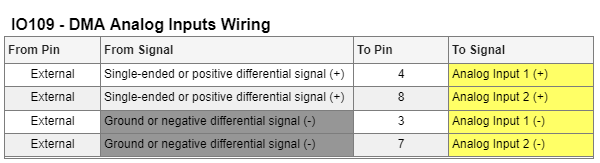

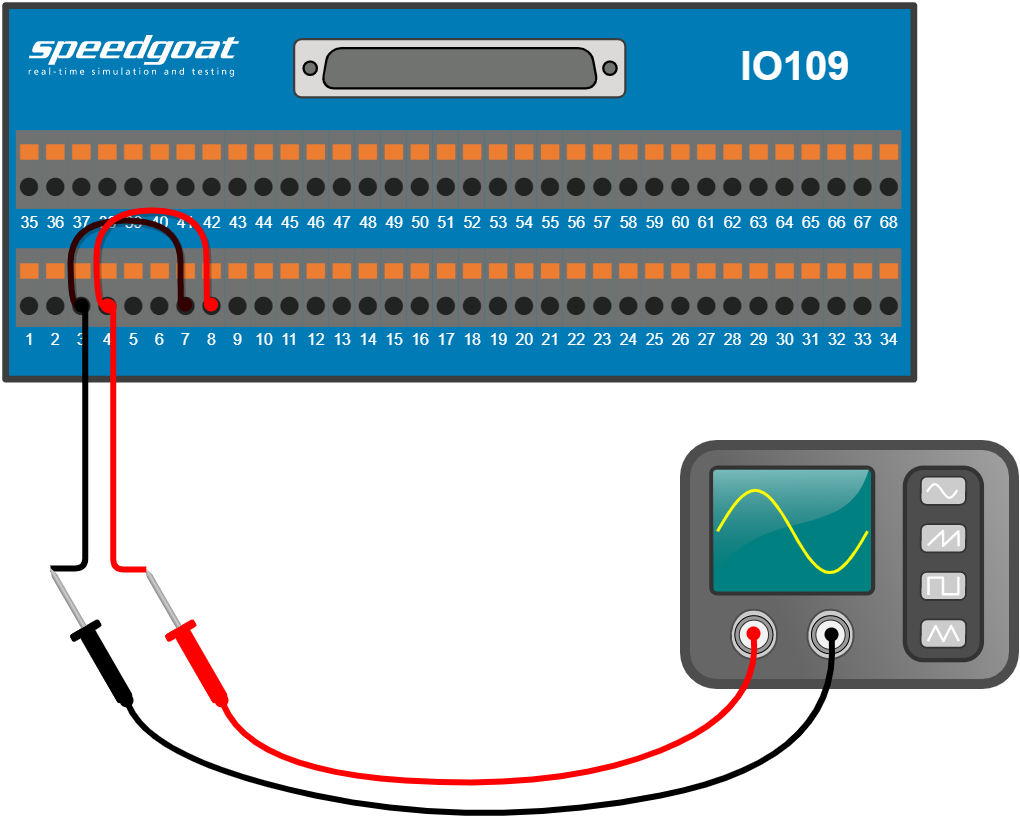

## Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO109_DMAAnalogInputs';
open_system(modelName);

### Model Description

The Simulink model features the [IO109 Analog Input (DMA) ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io109_analog_input_dma_v2)block. Analog Inputs 1 and 2 are enabled in this block.

Furthermore, the model features a [Speedgoat Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block, configured as model trigger. If you wish to reuse the example in a larger Simulink model, consider putting the Analog Input block into a [Function-Call Subsystem](https://mathworks.com/help/simulink/slref/functioncallsubsystem.html) and configuring the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block accordingly.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

By clicking on the scope after the model run has terminated, you should be able to see the input signals.

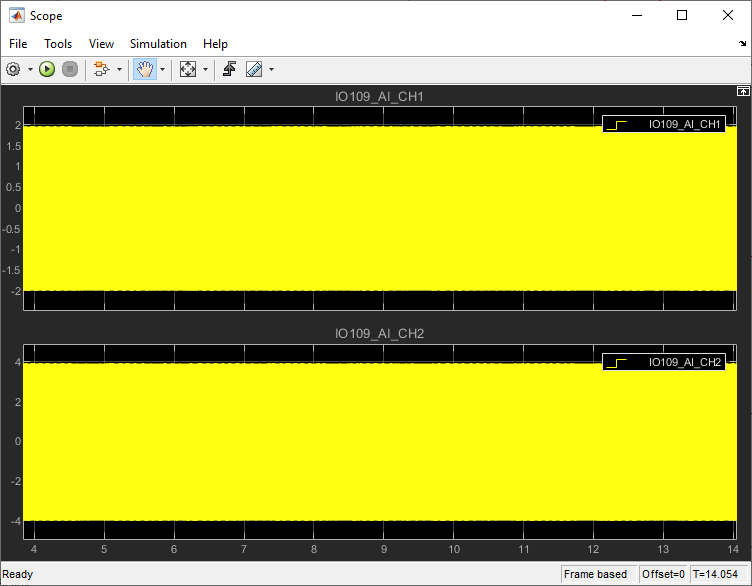

If you zoom in horizontally, you can see the increased sample rate thanks to the active DMA on the module. The model runs at a 1 kHz sample rate on the target machine, but the signals are sampled at a 10 kHz rate. The Analog Input block outputs frames of 10 samples per channel.

Ensure that in the Scope, under **View > Configuration Properties > Main**, the **Input Processing** option is set to **Columns as channels (frame based)**.

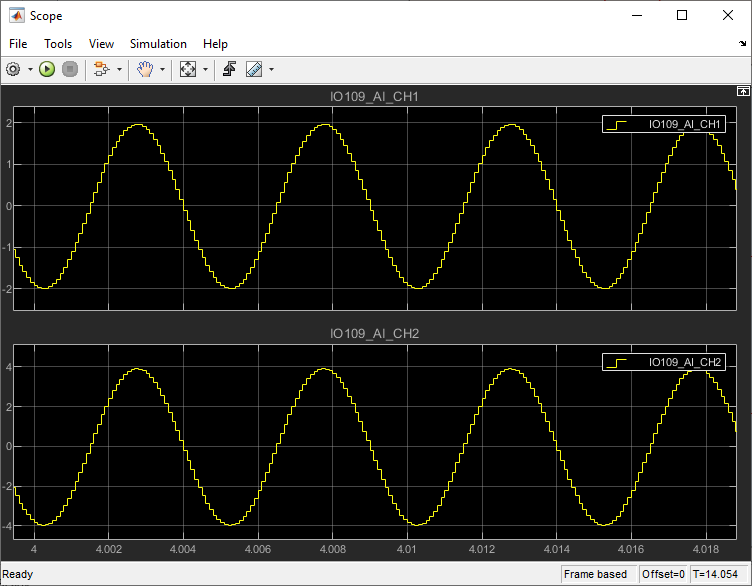

In the example shown above, a sine wave with amplitude 2 V and frequency 200 Hz was applied to the analog inputs. The value measured on channel 2 is multiplied with a factor of 2 before entering the Scope.

## Additional References

- [IO109 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io109)

- [DSP System Toolbox: Sample- and Frame-Based Concepts](https://mathworks.com/help/dsp/ug/sample-and-frame-based-concepts.html) 